# **树划分**

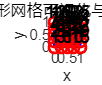

% 绘制网格图以及网格顶点索引
plot_2D_Mesh(coordinates, elements);

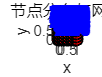

% 绘制节点图及索引
figure;
hold on;
% 1. 绘制物理单元网格
for i = 1:n_elements
    element_nodes = elements(:, i);
    element_coordinates = coordinates(element_nodes, :);
    
    % 绘制单元填充
    patch(element_coordinates(:, 1), element_coordinates(:, 2), 'c', 'FaceAlpha', 0.3);
    % 绘制单元边框
    line([element_coordinates(:,1); element_coordinates(1,1)], ...
         [element_coordinates(:,2); element_coordinates(1,2)], 'Color', 'k', 'LineWidth', 1);
end
% 2. 绘制节点并标注序号
scatter(unique_coords(:, 1), unique_coords(:, 2), 50, 'ro', 'filled', 'MarkerEdgeColor', 'k');

% 3. 为每个节点添加序号标签
for i = 1:length(unique_coords)
    text(unique_coords(i, 1), unique_coords(i, 2), sprintf('%d', index_points(i)), ...
         'HorizontalAlignment', 'center', ...
         'VerticalAlignment', 'bottom', ...
         'FontSize', 10, ...
         'Color', 'b', ...
         'FontWeight', 'bold');
end

% 4. 设置图形属性
axis equal; % 保持坐标轴比例 1:1
xlabel('x');
ylabel('y');
title('节点分布与网格');
grid on;
box on;

hold off;

% % 3. 统计每个唯一点的出现次数
% point_count = accumarray(ic, 1);  % 每个唯一点的出现次数
% 
% % 4. 确定边界点：出现次数小于4的点
% is_boundary = point_count > 1 & point_count < 5 ;  % 在四边形网格中，内部点通常出现4次
% 
% % 5. 获取边界点的索引（对应于去重后的唯一点的索引）
% boundary_indices = find(is_boundary);
% 
% % 6. 获取边界点的坐标
% boundary_points = unique_coords(boundary_indices, :);
% 
% % 7. 获取边界点在原始数据中的索引（可选）
% boundary_original_indices = ia(boundary_indices);
% 
% % % 输出结果
% % disp('边界点的坐标：');
% % disp(boundary_points);
% % disp('边界点在去重后唯一点的索引：');
% % disp(boundary_indices);
% % disp('每个边界点的出现次数：');
% % disp(point_count(boundary_indices));
% 
% % 可选：可视化验证
% figure;
% plot(all_points(:,1), all_points(:,2), 'b.', 'MarkerSize', 10); % 所有点
% hold on;
% plot(boundary_points(:,1), boundary_points(:,2), 'ro', 'MarkerSize', 12); % 边界点
% legend('所有点', '边界点');
% title('四边形网格中的边界点');
% grid on;

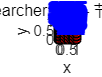

% %% 使用 KDTreeSearcher 构建k-d树并划分簇
% % 输入：
% % - unique_coords: 去重后的节点坐标 [x, y]
% % - min_size: 最小簇大小，控制划分终止
% 
% points = unique_coords; % 假设已有去重后的节点坐标
% min_size = 5; % 最小簇大小，可调整
% 
% % 构建k-d树模型
% kd_model = KDTreeSearcher(points);
% 
% % 初始化簇信息
% n_points = size(points, 1);
% cluster_ids = zeros(n_points, 1); % 每个点的簇序号
% current_cluster = 1;
% 
% % 调用递归划分函数
% [cluster_ids] = partition_space(kd_model, points, min_size, cluster_ids, current_cluster);
% 
% %% 递归划分函数
% function [cluster_ids, next_cluster] = partition_space(kd_model, points, min_size, cluster_ids, current_cluster)
%     % 输入：
%     % - kd_model: KDTreeSearcher对象
%     % - points: 当前区域的节点坐标
%     % - min_size: 最小簇大小
%     % - cluster_ids: 全局簇序号数组
%     % - current_cluster: 当前簇序号
%     % 输出：
%     % - cluster_ids: 更新后的簇序号数组
%     % - next_cluster: 下一个可用簇序号
% 
%     n_points = size(points, 1);
% 
%     % 如果点数小于阈值，分配当前簇序号并返回
%     if n_points <= min_size
%         % 找到这些点在原始数据中的索引
%         [idx, ~] = knnsearch(kd_model, points, 'K', 1);
%         cluster_ids(idx) = current_cluster;
%         next_cluster = current_cluster + 1;
%         return;
%     end
% 
%     % 计算当前区域边界
%     x_min = min(points(:, 1));
%     x_max = max(points(:, 1));
%     y_min = min(points(:, 2));
%     y_max = max(points(:, 2));
% 
%     % 选择分割维度（基于范围）
%     if (x_max - x_min) > (y_max - y_min)
%         split_dim = 1; % x轴
%         split_value = (x_min + x_max) / 2;
%     else
%         split_dim = 2; % y轴
%         split_value = (y_min + y_max) / 2;
%     end
% 
%     % 分割点集
%     if split_dim == 1
%         left_points = points(points(:, 1) <= split_value, :);
%         right_points = points(points(:, 1) > split_value, :);
%     else
%         left_points = points(points(:, 2) <= split_value, :);
%         right_points = points(points(:, 2) > split_value, :);
%     end
% 
%     % 递归划分左右子区域
%     if ~isempty(left_points)
%         [cluster_ids, next_cluster] = partition_space(kd_model, left_points, min_size, cluster_ids, current_cluster);
%     else
%         next_cluster = current_cluster;
%     end
% 
%     if ~isempty(right_points)
%         [cluster_ids, next_cluster] = partition_space(kd_model, right_points, min_size, cluster_ids, next_cluster);
%     end
% end
% 
% %% 绘图
% figure;
% hold on;
% 
% % 绘制网格
% for i = 1:n_elements
%     element_nodes = elements(:, i);
%     element_coordinates = coordinates(element_nodes, :);
%     patch(element_coordinates(:, 1), element_coordinates(:, 2), 'c', 'FaceAlpha', 0.3);
%     line([element_coordinates(:,1); element_coordinates(1,1)], ...
%          [element_coordinates(:,2); element_coordinates(1,2)], 'Color', 'k');
% end
% 
% % 绘制所有节点（统一红色）
% scatter(points(:, 1), points(:, 2), 25, 'ro', 'filled', 'MarkerEdgeColor', 'k');
% 
% % 标注簇序号
% for i = 1:n_points
%     text(points(i, 1), points(i, 2), num2str(cluster_ids(i)), ...
%          'HorizontalAlignment', 'center', ...
%          'VerticalAlignment', 'bottom', ...
%          'FontSize', 12, ...
%          'Color', 'b', ...
%          'FontWeight', 'bold');
% end
% 
% % 设置图形属性
% axis equal;
% xlabel('x');
% ylabel('y');
% title('KDTreeSearcher划分 - 节点标注簇序号');
% grid on;
% box on;
% hold off;
% 
% %% 统计信息

% unique_clusters = unique(cluster_ids);
% disp(['总簇数: ', num2str(length(unique_clusters))]);
% for i = 1:length(unique_clusters)
%     cluster_size = sum(cluster_ids == unique_clusters(i));

总簇数: 55


%     disp(['簇 ', num2str(unique_clusters(i)), ' 节点数: ', num2str(cluster_size)]);
% end


% %% 绘图

簇 1 节点数: 4
簇 2 节点数: 4
簇 3 节点数: 4
簇 4 节点数: 4
簇 5 节点数: 2
簇 6 节点数: 4
簇 7 节点数: 2
簇 8 节点数: 4
簇 9 节点数: 2
簇 10 节点数: 4
簇 11 节点数: 2
簇 12 节点数: 4
簇 13 节点数: 3
簇 14 节点数: 2
簇 15 节点数: 4
簇 16 节点数: 2
簇 17 节点数: 4
簇 18 节点数: 2
簇 19 节点数: 4
簇 20 节点数: 2
簇 21 节点数: 4
簇 22 节点数: 2
簇 23 节点数: 4
簇 24 节点数: 3
簇 25 节点数: 2
簇 26 节点数: 4
簇 27 节点数: 3
簇 28 节点数: 2
簇 29 节点数: 4
簇 30 节点数: 2
簇 31 节点数: 4
簇 32 节点数: 2
簇 33 节点数: 4
簇 34 节点数: 2
簇 35 节点数: 4
簇 36 节点数: 2
簇 37 节点数: 4
簇 38 节点数: 3
簇 39 节点数: 2
簇 40 节点数: 4
簇 41 节点数: 3
簇 42 节点数: 2
簇 43 节点数: 4
簇 44 节点数: 3
簇 45 节点数: 2
簇 46 节点数: 4
簇 47 节点数: 3
簇 48 节点数: 2
簇 49 节点数: 4
簇 50 节点数: 3
簇 51 节点数: 2
簇 52 节点数: 4
簇 53 节点数: 3
簇 54 节点数: 2
簇 55 节点数: 4


% figure;
% hold on;
% 
% % 方法1：使用scatter绘制每个点，按簇着色
% scatter(points(:,1), points(:,2), 50, cluster_ids, 'filled');
% colormap(jet(max(cluster_ids))); % 设置颜色图
% colorbar; % 显示颜色条
% title('K-D Tree Space Partitioning');
% xlabel('X');
% ylabel('Y');
% 
% % 方法2：绘制网格边界（可选）
% % 获取所有唯一的簇ID
% unique_clusters = unique(cluster_ids);
% for i = 1:length(unique_clusters)
%     cluster_points = points(cluster_ids == unique_clusters(i), :);
%     if ~isempty(cluster_points)
%         % 计算每个簇的边界
%         x_min = min(cluster_points(:,1));
%         x_max = max(cluster_points(:,1));
%         y_min = min(cluster_points(:,2));
%         y_max = max(cluster_points(:,2));
% 
%         % 绘制矩形边界
%         rectangle('Position', [x_min, y_min, x_max-x_min, y_max-y_min], ...
%                  'EdgeColor', 'k', 'LineWidth', 1);
%     end
% end
% 
% grid on;
% axis equal; % 保持x和y轴比例一致
% hold off;

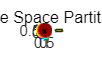

points = unique_coords; % 节点坐标
min_size = 5; % 最小簇大小，可调整


% 构建k-d树模型
kd_model = KDTreeSearcher(points);

% 初始化簇信息
n_points = size(points, 1);
cluster_ids = zeros(n_points, 1); % 每个点的簇序号
current_cluster = 1;

% 初始化分割线存储
split_lines = []; % 格式：[x1, y1, x2, y2, split_dim]

% 调用递归划分函数
[cluster_ids, ~, split_lines] = partition_space(kd_model, points, min_size, cluster_ids, current_cluster, split_lines);

%% 递归划分函数
function [cluster_ids, next_cluster, split_lines] = partition_space(kd_model, points, min_size, cluster_ids, current_cluster, split_lines)
    n_points = size(points, 1);
    
    if n_points <= min_size
        [idx, ~] = knnsearch(kd_model, points, 'K', 1);
        cluster_ids(idx) = current_cluster;
        next_cluster = current_cluster + 1;
        return;
    end
    % 计算当前区域边界
    x_min = min(points(:, 1));
    x_max = max(points(:, 1));
    y_min = min(points(:, 2));
    y_max = max(points(:, 2));
    % 选择分割维度（基于范围）
    if (x_max - x_min) > (y_max - y_min)
        split_dim = 1; % x轴
        split_value = (x_min + x_max) / 2;
        new_line = [split_value, y_min, split_value, y_max, split_dim];
    else
        split_dim = 2; % y轴
        split_value = (y_min + y_max) / 2;
        new_line = [x_min, split_value, x_max, split_value, split_dim];
    end
    
    split_lines = [split_lines; new_line];
    % 分割点集
    if split_dim == 1
        left_points = points(points(:, 1) <= split_value, :);
        right_points = points(points(:, 1) > split_value, :);
    else
        left_points = points(points(:, 2) <= split_value, :);
        right_points = points(points(:, 2) > split_value, :);
    end
    
    next_cluster = current_cluster;
    % 递归划分左右子区域
    if ~isempty(left_points)
        [cluster_ids, next_cluster, split_lines] = partition_space(kd_model, left_points, min_size, cluster_ids, current_cluster, split_lines);
    end
    
    if ~isempty(right_points)
        [cluster_ids, next_cluster, split_lines] = partition_space(kd_model, right_points, min_size, cluster_ids, next_cluster, split_lines);
    end
end

%% 绘图
figure;
hold on;

% 获取整个点集的边界，用于无限长分割线
x_range = [min(points(:, 1)), max(points(:, 1))];
y_range = [min(points(:, 2)), max(points(:, 2))];

% 绘制所有点，统一颜色（蓝色），并标注簇序号
scatter(points(:, 1), points(:, 2), 50, 'b', 'filled'); % 蓝色填充点
for i = 1:size(points, 1)
    text(points(i, 1), points(i, 2), sprintf('%d', cluster_ids(i)), ...
         'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', ...
         'FontSize', 8, 'Color', 'k');
end

% 绘制无限长虚线分割线
if ~isempty(split_lines) && size(split_lines, 2) == 5
    for i = 1:size(split_lines, 1)
        split_line = split_lines(i, :);
        if split_line(5) == 1 % 垂直线 (x轴分割)
            plot([split_line(1), split_line(1)], [y_range(1), y_range(2)], 'k--', 'LineWidth', 1.5);
        else % 水平线 (y轴分割)
            plot([x_range(1), x_range(2)], [split_line(2), split_line(2)], 'k--', 'LineWidth', 1.5);
        end
    end
else
    warning('split_lines is empty or has incorrect format.');
end

title('K-D Tree Space Partitioning with Infinite Dashed Lines');
xlabel('X');
ylabel('Y');
grid on;
axis equal;
hold off;
